## clear variables

clc
clear
close all

## addpath fieldtrip

addpath  C:\Users\gvelasquez\Documents\MATLAB\fieldtrip-20230716\
ft_defaults

## Read MRI and determine coordinate system

PID = 'YNH28';
mri =ft_read_mri([PID '_T1_w.nii.gz']);

extracting compressed dataset to C:\Users\gvelasquez\AppData\Local\Temp\x376618031f9d566f42ebb4ff5d62643a\...
extracted dataset is located at C:\Users\gvelasquez\AppData\Local\Temp\x376618031f9d566f42ebb4ff5d62643a\YNH37_T1_w.nii


the coordinate system appears to be 'scanras'


the input is volume data with dimensions [193 229 193]
voxel size along 1st dimension (i) : 1.000000 mm
voxel size along 2nd dimension (j) : 1.000000 mm
voxel size along 3rd dimension (k) : 1.000000 mm
volume per voxel                   : 1.000000 mm^3
the input is volume data with dimensions [193 229 193]
voxel size along 1st dimension (i) : 1.000000 mm
voxel size along 2nd dimension (j) : 1.000000 mm
voxel size along 3rd dimension (k) : 1.000000 mm
volume per voxel                   : 1.000000 mm^3
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1894
 In ft_sourceplot at line 1141

Press "h" to show this help.
Press "1", "2", or "3" to switch to the corresponding subplot.
Use the arrow keys to navigate in the current axis.
Click left mouse button to reposition the cursor.
Click and hold right mouse button to update the position while moving the mouse.
the call to "ft_sourceplot" took 2 seconds


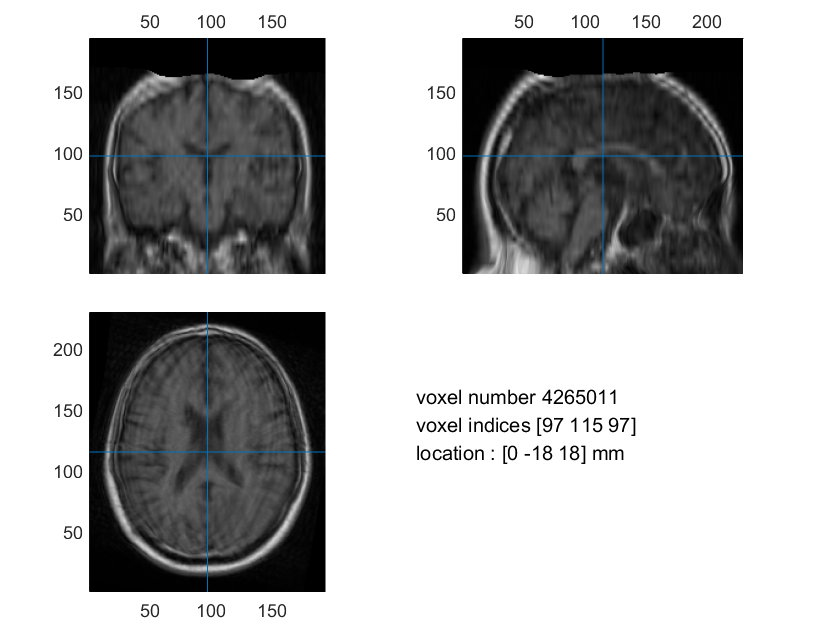


cfg = [];
ft_sourceplot(cfg, mri);

The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm


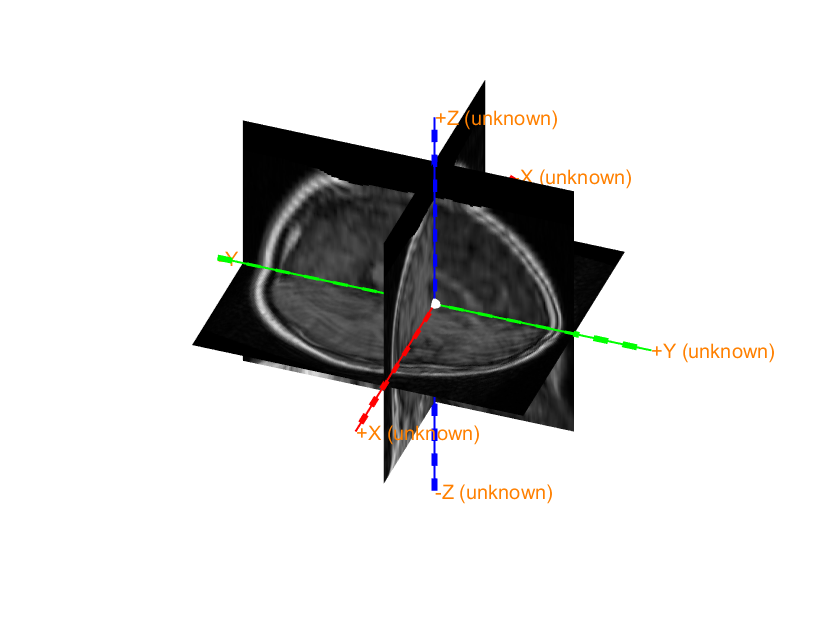

The coordinate system is not specified.



mri = ft_determine_coordsys(mri);

## Aligh MRI to CTF coordinate system

cfg = [];
cfg.method = 'interactive';
cfg.coordsys = 'ctf';
mri  = ft_volumerealign(cfg,mri);

cfg = [];
ft_sourceplot(cfg, mri);

## segmentation of brain

cfg           = [];
cfg.brainthreshold = 0.5;
cfg.scalpthreshold = 0.05;%default is 0.1
cfg.spmmethod = 'old';
cfg.skullthreshold = 0.5;
cfg.brainsmooth   = 5;
cfg.scalpsmooth    = 13;
cfg.skullsmooth = 5;
cfg.output    = {'brain','skull','scalp'};
segmentedmri  = ft_volumesegment(cfg, mri);


cfg              = [];
cfg.funparameter = 'scalp';%check the brain and skull too
ft_sourceplot(cfg,segmentedmri);

cfg=[];
cfg.tissue={'brain','skull','scalp'};
cfg.numvertices = [3000 2000 1000];
bnd = ft_prepare_mesh(cfg,segmentedmri);


figure
ft_plot_mesh(bnd(3), 'facecolor',[0.2 0.2 0.2], 'facealpha', 0.3, 'edgecolor', [1 1 1], 'edgealpha', 0.05);
hold on;
ft_plot_mesh(bnd(2),'edgecolor','none','facealpha',0.4);
hold on;
ft_plot_mesh(bnd(1),'edgecolor','none','facecolor',[0.4 0.6 0.4]);

## Create head model

cfg        = [];
cfg.conductivity = [1 1/8 1] * 0.33;
%cfg.method ='dipoli'; % You can also specify 'openmeeg', 'bemcp', or another method.dipoli
cfg.method ='bemcp';
vol        = ft_prepare_headmodel(cfg, bnd);

## Align electrode in MRI coordinate space

sens=ft_read_sens('standard_1020.elc');
newsens = ft_determine_units(sens);
labels = {'Fp1', 'Fp2', 'F3', 'F4', 'C3', 'C4', 'P3', 'P4', 'O1', 'O2', 'F7', 'F8', 'T3', 'T4', 'T5' 'T6', 'Fz', 'Cz', 'Pz'};
usedelec = [1:19];
ss = length(labels)+3;
newsens.chanpos= sens.chanpos(1:ss, :);
newsens.elecpos= sens.elecpos(1:ss, :);
newsens.label =sens.label(1:ss);
newsens.chantype = sens.chantype(1:ss);
newsens.chanunit = sens.chanunit(1:ss);
strlabel = lower(string(sens.label));

for i = 1:length(labels)
    nameA = lower(labels{i});
    ix = find(nameA == strlabel);
    newsens.chanpos(i+ 3, :)= sens.chanpos(ix, :);
    newsens.elecpos(i+3, :)= sens.elecpos(ix, :);
    newsens.label(i+3) =sens.label(ix);
end


vox_Nas = mri.cfg.fiducial.nas;  % fiducials saved in mri structure
vox_Lpa = mri.cfg.fiducial.lpa;
vox_Rpa = mri.cfg.fiducial.rpa;
vox2head = mri.transform; % transformation matrix of individual MRI

% transform voxel indices to MRI head coordinates
head_Nas = ft_warp_apply(vox2head, vox_Nas, 'homogenous'); % nasion
head_Lpa = ft_warp_apply(vox2head, vox_Lpa, 'homogenous'); % Left preauricular
head_Rpa = ft_warp_apply(vox2head, vox_Rpa, 'homogenous'); % Right preauricular

elec_mri.chanpos = [head_Nas;head_Lpa; head_Rpa];
elec_mri.elecpos = [head_Nas;head_Lpa; head_Rpa];
elec_mri.label = {'Nz', 'LPA', 'RPA'};
elec_mri.unit  = 'mm';

cfg = [];
cfg.method   = 'fiducial';
cfg.template = elec_mri;
cfg.elec     = newsens;
cfg.fiducial = {'Nz', 'LPA', 'RPA'};
elec_new = ft_electroderealign(cfg);

cfg = [];
cfg.method    = 'interactive';
cfg.elec      =elec_new;
cfg.headshape = vol.bnd(1);
elec_new1 = ft_electroderealign(cfg);


cfg = [];
cfg.method    = 'project';
cfg.elec      = elec_new1;
cfg.headshape = vol.bnd(1);
elec_new1 = ft_electroderealign(cfg);

figure;
ft_plot_sens(elec_new1,  'label', 'on');
hold on;
ft_plot_mesh(vol.bnd(1),'facealpha', 1, 'edgecolor', 'none', ...
    'facecolor', [0.65 0.65 0.65]); %scalp

## Source model

% elec_new1.chanpos = elec_new1.chanpos(4:end, :);
% elec_new1.chantype = elec_new1.chantype(4:end);
% elec_new1.chanunit = elec_new1.chanunit(4:end);
% elec_new1.elecpos = elec_new1.elecpos(4:end, :);
% elec_new1.label = elec_new1.label(4:end);

cfg = [];
cfg.channel = elec_new1.label(4:end);
elec_new1 = ft_selectdata(cfg, elec_new1);






cfg                 = [];
cfg.resolution = 5; %in mm
cfg.headmodel       = vol
cfg.inwardshift     =5; %shifts dipoles away from surfaces
sourcemodel         = ft_prepare_sourcemodel(cfg);

figure
hold on
ft_plot_headmodel(vol, 'facecolor', 'cortex', 'edgecolor', 'none');alpha 0.5; camlight;
ft_plot_mesh(sourcemodel.pos(sourcemodel.inside,:));

## prepare leadfield

[headmodel_fem_eeg_tr, elec] = ft_prepare_vol_sens(vol, elec_new1);
cfg               = [];
cfg.sourcemodel          = sourcemodel;
cfg.headmodel     = headmodel_fem_eeg_tr;
cfg.elec          = elec;
cfg.reducerank    = 3;
cfg.backproject = 'no';
leadfield_bem_eeg = ft_prepare_leadfield(cfg);




leadfdc = leadfield_bem_eeg;

insideix = find(leadfdc.inside==1);
LFmatrix = zeros([length(leadfdc.label), sum(leadfdc.inside) * 3]);
index = insideix;
for i = 1:length(insideix)
    ix = insideix(i);
    temp = leadfdc.leadfield{ix};
    LFmatrix(:, ((i-1)* 3+1) : (3 * i)) = temp;
end

for i=1:size(LFmatrix,2)
    LFmatrix(:,i) = LFmatrix(:,i)./sqrt(sum(LFmatrix(:,i).^2));
end

leadfdc.label(1:length(labels))= strcat('E',  leadfdc.label(1:length(labels)));
elec.label = leadfdc.label(1:length(labels));

%%%load time series data
Y_tot=load('preprocessed_5487b07d360d12cac95cd242ec8e88e70d07081db1afe9cfca1a0bbfd670e4c7_20150403_080022.edf.mat')

% %%%you will need to do data processing including filtering, decimate, etc. You will also need to select a period of time instead of using entire sequence.
% Y_tot = detrend(transpose(Y_tot));
% Y_tot = transpose(Y_tot);
% y = transpose(Y_tot);
% sigu_init =norm(transpose(y)*y)*eye(size(y,2))*1e-6;
% [gamma,x_ChangHeteroChamp_ori,w,c,LK_ChampCC1,noise_hetero] = champ_noise_up(Y_tot, LFmatrix, sigu_init,80,nd = 1,  vcs = 0,  plot_on = 1, coup= 0, noup=0,ncf = 0, 1e-6);
% apower1 = zeros((size(x_ChangHeteroChamp_ori, 1)/3), (size(x_ChangHeteroChamp_ori, 2)));
% apower2 = apower1;
% apower3 =apower1;
%
% for i = 1:(size(x_ChangHeteroChamp_ori, 1)/3)
% 	  apower1(i, :)= x_ChangHeteroChamp_ori((3 * (i-1) + 1), :); ...
% apower2(i, :)= x_ChangHeteroChamp_ori((3 * (i-1) + 2), :); ...
% apower3(i, :)= x_ChangHeteroChamp_ori((3 * (i-1) + 3), :); ...
%
% end
%
% avgpower = (apower1.^2 + apower2.^2 + apower3.^2)/3;
% maxpower = sum(avgpower, 2);
% dirpower = [sum(apower1.^2, 2) sum(apower2.^2, 2) sum(apower3.^2, ...
% 						      2)];
% dirpower = dirpower/max(max(dirpower));
%
% stime = 1:size(avgpower, 2);
% [B, I1] = sort(-sum(avgpower(:, :), 2));
% selectpower = [apower1(I1(1:2), :); apower2(I1(1:2), :); apower3(I1(1:2), :)];
% leadfd.pos(index(I1(1:20)), :) %* 100
% plot(transpose(avgpower(I1(1:2), :)))
% cfg = [];
% cfg.locationcoordinates = 'head'
% cfg.location = leadfd.pos(index(I1(1:20)), :)
% cfg.location  = cfg.location(1,    :)
% ft_sourceplot( cfg, mri)